ans = 15.1733

ans = 7.0521

optrank_b = 1

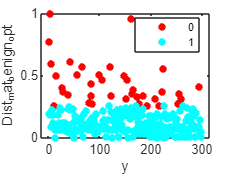

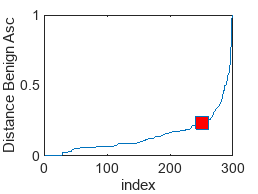

error_malignant_in =    13.5480   26.7447   23.6132   26.2102   30.1814


optrank_m = 1

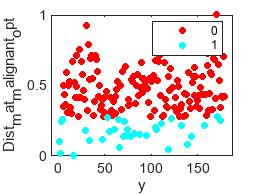

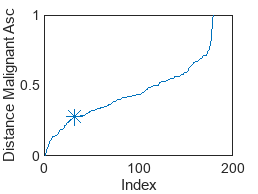

ans = 17.7831

ans = 7.6372

optrank_b = 1

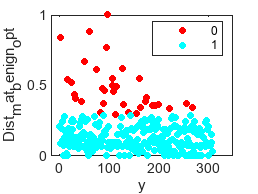

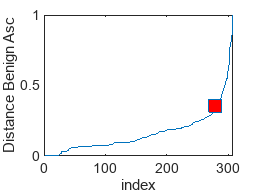

error_malignant_in =    24.4786   31.7673   23.0618   33.2075   33.6174


optrank_m = 3

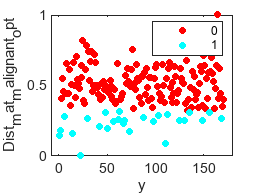

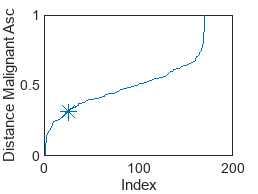

ans = 17.5278

ans = 7.0817

optrank_b = 1

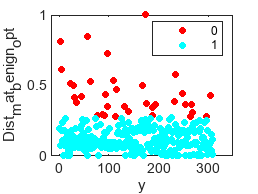

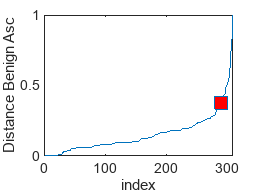

error_malignant_in =    24.4635   25.2691   35.3983   35.2530   34.9806


optrank_m = 1

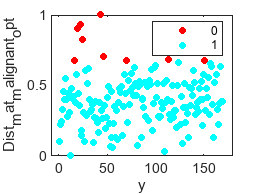

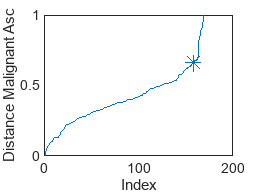

ans = 14.5615

ans = 7.0581

optrank_b = 1

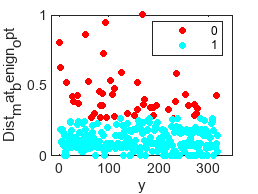

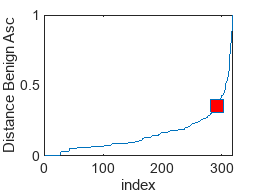

error_malignant_in =    22.1178   25.6154   25.2017   32.8075   35.2731


optrank_m = 1

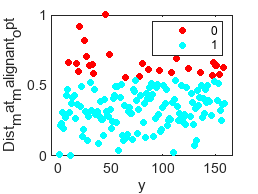

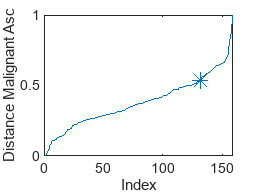

ans = 19.3083

ans = 7.1052

optrank_b = 1

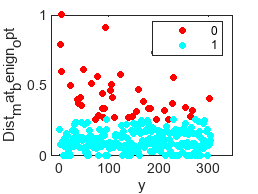

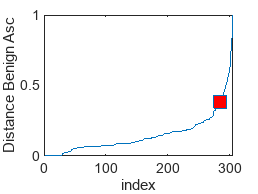

error_malignant_in =    24.2511   25.1870   26.3018   31.9512   29.7853


optrank_m = 1

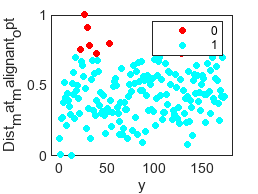

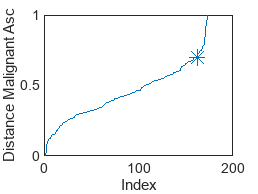

ans = 17.8167

ans = 7.1714

optrank_b = 1

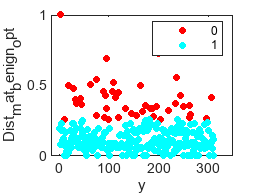

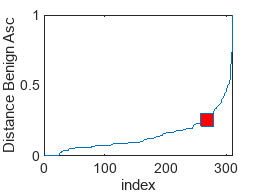

error_malignant_in =    23.5872   24.8231   24.4886   33.2844   33.1803


optrank_m = 1

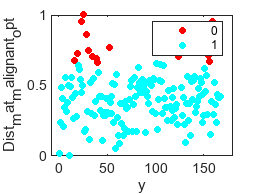

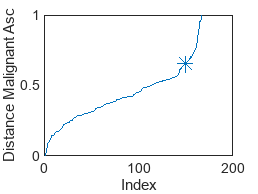

ans = 18.9136

ans = 7.0942

optrank_b = 1

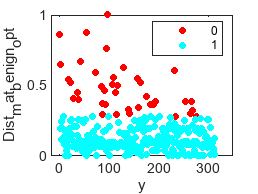

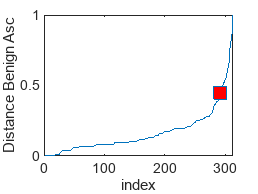

error_malignant_in =    24.0496   27.2557   35.3511   32.0860   32.8601


optrank_m = 1

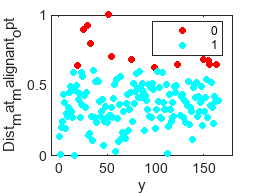

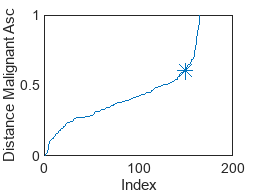

ans = 19.3692

ans = 7.6310

optrank_b = 1

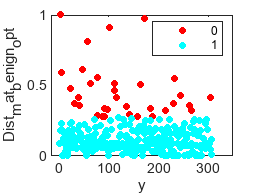

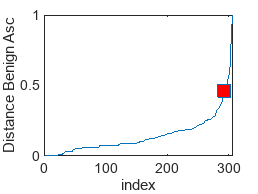

error_malignant_in =    24.4789   23.8764   35.7894   35.7413   35.5555


optrank_m = 2

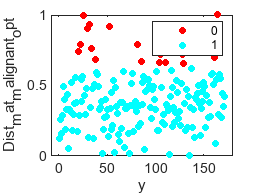

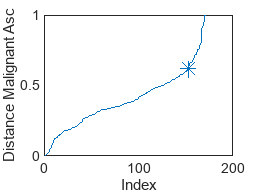

ans = 15.0391

ans = 7.4879

optrank_b = 1

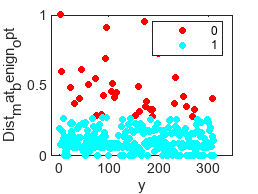

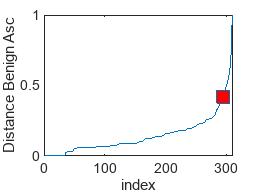

error_malignant_in =    24.8555   24.5715   24.9495   35.4776   35.1555


optrank_m = 2

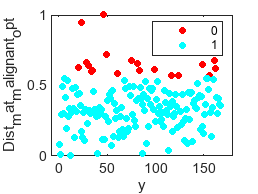

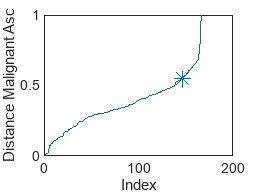

ans = 17.8575

ans = 7.6486

optrank_b = 1

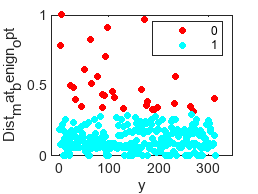

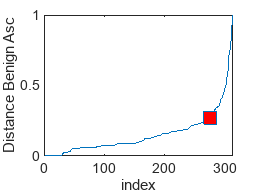

error_malignant_in =    24.5955   26.2295   23.3378   34.2915   34.7876


optrank_m = 3

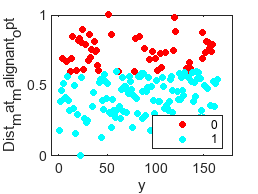

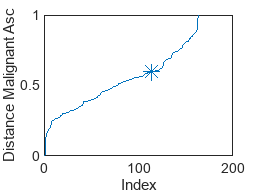

for j = [1,2,3,4,5,6,7,8,9,10]
    figure

    splitfolder=strcat('split',num2str(j));
    per =0;%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
        cd (splitfolder)

        folder=strcat('per',num2str(percent));
        cd (folder)
        my_file = strcat('cell_sample_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        benign=File(File(:,10)==2,1:9);
        T_benign=benign.';
        malignant=File(File(:,10)==4,1:9);
        T_malignant=malignant.';

        folder_l1=strcat('ACE_dist_rankselect_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,2,3,4,5];

        error_benign = nan(size(ranks));
        error_benign_in = nan(size(ranks));
        numbenign=length(T_benign);
        Dist_mat_benign_array=nan(length(ranks),numbenign);
        threshold_rank_b=nan(size(ranks));
        elbow_indx_rank_b=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering\

            T_benign_temp=T_benign;
            Dist_mat_benign=[];


            BF_benign=l1pca_BF(T_benign,i,1,10,10,'');
            for k = 1 : numbenign
                A=T_benign(:,k);
                Dist_mat_benign(k)=norm((A-(BF_benign*BF_benign.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_benign,[],"all");
            max_val=max(Dist_mat_benign,[],"all");
            Dist_mat_benign= Dist_mat_benign-min_val;%]/[max_val-min_val]
            Dist_mat_benign=Dist_mat_benign /(max_val-min_val);


            Dist_mat_benign_array(i,:)=Dist_mat_benign;
            [Dist_mat_benign_asc,Indx_b]=sort(Dist_mat_benign,"ascend");


            [elbow_b_err,elbow_indx_b]=knee_pt(Dist_mat_benign_asc);

            error_benign(i)=elbow_b_err;
            threshold_rank_b(i)=Dist_mat_benign_asc(elbow_indx_b);
            elbow_indx_rank_b(i)=elbow_indx_b;


            index_b_in=find(Dist_mat_benign<Dist_mat_benign_asc(elbow_indx_b));
            Rec_mat_benign_in=T_benign_temp(:,index_b_in);

           Dist_mat_benign_inerr=[];%nan(size(Rec_mat_benign_in));
           BF_benign_l1=l1pca_BF(Rec_mat_benign_in,1,1,10,10,'');
            
%             for b = 1 : length(Rec_mat_benign_in)
%                 B=Rec_mat_benign_in(:,b);
%                 Dist_mat_benign_inerr(b)=norm((B-(BF_benign_l1*BF_benign_l1.'*B)),1);
%                 
%             end
%             Dist_mat_benign_inerr=Dist_mat_benign_inerr-min(Dist_mat_benign_inerr);
%             Dist_mat_benign_inerr=Dist_mat_benign_inerr/(max(Dist_mat_benign_inerr)-min(Dist_mat_benign_inerr));

            error_benign_in(i)=norm(Rec_mat_benign_in-(BF_benign_l1*BF_benign_l1.'*Rec_mat_benign_in),1);
            %err_whole(Dist_mat_benign_inerr);
%             % norm(Rec_mat_benign_in-(BF_benign_l1*BF_benign_l1.'*Rec_mat_benign_in),1)
            %


        end
        

       max(error_benign_in)
       min(error_benign_in)

        [~,optrank_b]= min(error_benign_in)

        Dist_mat_benign_opt=Dist_mat_benign_array(optrank_b,:);
        threshold_dist_b= threshold_rank_b(optrank_b);
        elbow_indx_b_opt=elbow_indx_rank_b(optrank_b);

        ind_O_b=find(Dist_mat_benign_opt>threshold_dist_b);
        ind_I_b=find(Dist_mat_benign_opt<=threshold_dist_b);


        cluster_b=zeros(size(Dist_mat_benign_opt));
        cluster_b(ind_I_b)=1;
        figure
        y= 1:1:length(benign);
        numGroups = length(unique(cluster_b));
        gscatter(y,Dist_mat_benign_opt,cluster_b,hsv(numGroups))

        figure
        plot(sort(Dist_mat_benign_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_b),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel("Distance Benign Asc")
        ind_O_b;


        T_benign_temp(:,ind_O_b)=[];
        length(T_benign_temp);

        Final_benign=T_benign_temp';
        Final_benign(:,10)=2;

    end
    %
    %
    %    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    nummalignant=length(T_malignant);
    error_malignant=nan(size(ranks));
    error_malignant_in=nan(size(ranks));
    Dist_mat_mal_array=nan(length(ranks),nummalignant);
    threshold_rank_m=nan(size(ranks));
    elbow_rank_m=nan(size(ranks));


    for i=ranks
        %fprintf("Rank is %i \n", i) %i);

        T_malignant_temp=T_malignant;
        Dist_mat_malignant=[];

        BF_malignant=l1pca_BF(T_malignant,i,1,10,10,'');
        for k = 1 : nummalignant
            A=T_malignant(:,k);
            Dist_mat_malignant(k)=norm((A-(BF_malignant*BF_malignant.'*A)),1);
            k;
        end

        Dist_mat_malignant;
        min_val=min(Dist_mat_malignant,[],"all");
        max_val=max(Dist_mat_malignant,[],"all");
        Dist_mat_malignant= Dist_mat_malignant -min_val;%]/[max_val-min_val]
        Dist_mat_malignant=Dist_mat_malignant /(max_val-min_val);
        Dist_mat_mal_array(i,:)=Dist_mat_malignant;

        [Dist_mat_malignant_asc,Indx_m]=sort(Dist_mat_malignant,"ascend");


        [elbow_m_err,elbow_indx_m]=knee_pt(Dist_mat_malignant_asc);

        error_malignant(i)=elbow_m_err;
        threshold_rank_m(i)=Dist_mat_malignant_asc(elbow_indx_m);
        elbow_rank_m(i)=elbow_indx_m;

        index_m_in=find(Dist_mat_malignant<Dist_mat_malignant_asc(elbow_indx_m));
        Rec_mat_malignant_in=T_malignant(:,index_m_in);
        
        Dist_mat_malignant_inerr=[];%nan(size(Rec_mat_malignant_in));
        BF_malignant_l1=l1pca_BF(Rec_mat_malignant_in,1,1,10,10,'');
%         for n = 1 : length(Rec_mat_malignant_in)
%             M=Rec_mat_malignant_in(:,n);
%             Dist_mat_malignant_inerr(n)=norm((M-(BF_malignant_l1*BF_malignant_l1.'*M)),1);       
%         end
%         
%         Dist_mat_malignant_inerr=(Dist_mat_malignant_inerr-min(Dist_mat_malignant_inerr));
%         Dist_mat_malignant_inerr=Dist_mat_malignant_inerr/(max(Dist_mat_malignant_inerr)-min(Dist_mat_malignant_inerr));
%     
        error_malignant_in(i)=norm(Rec_mat_malignant_in-(BF_malignant_l1*BF_malignant_l1.'*Rec_mat_malignant_in),1);
        %err_whole(Dist_mat_malignant_inerr);
        %norm(Rec_mat_malignant_in-(BF_malignant_l1*BF_malignant_l1.'*Rec_mat_malignant_in),1);
        %err_whole(Dist_mat_malignant_inerr);

    end
    error_malignant_in
    [~,optrank_m]= min(error_malignant_in)

    Dist_mat_malignant_opt=Dist_mat_mal_array(optrank_m,:);
    threshold_dist_m= threshold_rank_m(optrank_m);
    elbow_indx_m_opt=elbow_rank_m(optrank_m);

    ind_O_m=find(Dist_mat_malignant_opt>threshold_dist_m);
    ind_I_m=find(Dist_mat_malignant_opt<=threshold_dist_m);

    cluster_m=zeros(size(Dist_mat_malignant_opt));
    cluster_m(ind_I_m)=1;

    figure
    y= 1:1:length(malignant);
    numGroups = length(unique(cluster_m));
    gscatter(y,Dist_mat_malignant_opt,cluster_m,hsv(numGroups))

    figure
    plot(sort(Dist_mat_malignant_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_m_opt),'MarkerFaceColor','red','MarkerSize',10 )
    xlabel("Index")
    ylabel("Distance Malignant Asc")
    ind_O_m;


    T_malignant_temp(:,ind_O_m)=[];
    length(T_malignant_temp);

    Final_malignant=T_malignant_temp';
    Final_malignant(:,10)=4;


    cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
    cd (splitfolder)
    cd (folder)

    cd (folder_l1)

    L1pca_file=(horzcat(Final_benign.',Final_malignant.')).';

    L1pca_file = array2table(L1pca_file);
    L1pca_file.Properties.VariableNames(1:10)=  {'Clump','UnifSize','UnifShape','MargAdh','SingEpiSize','BareNuc','BlandChrom','NormNucl','Mit','Class'};
    filel1pca=strcat('cell_sample_misclass_per',num2str(percent),'_ACE_l1pca.csv');
    writetable(L1pca_file,filel1pca);

end